clear cube
data_src = "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-along_side_run_0\measurement_001";

dr = dca1000FileReader("RecordLocation",data_src)

dr =   dca1000FileReader with properties:

              BoardName: "IWR1843BOOST"
             ConfigFile: "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-along_side_run_0\measurement_001\iqData_ConfigFile.cfg"
         RecordLocation: "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-along_side_run_0\measurement_001"
       RecordFilePrefix: "iqData"
           NumDataCubes: 702 

Show all functions


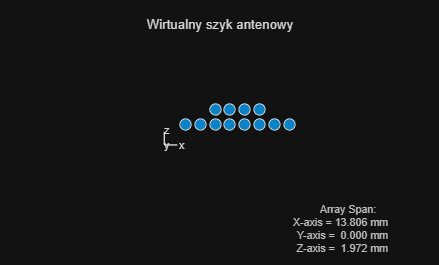

radarConfiguration=load(fileWithSuffix(data_src,"mat"),"RecordingParameters").RecordingParameters;
gifFile = data_src+'\output.gif';


c = physconst("LightSpeed");
fs = radarConfiguration.ADCSampleRate*1e3;
sweepSlope = radarConfiguration.SweepSlope*1e6/1e-6;
fc = radarConfiguration.CenterFrequency*1e9;
prf = 1e6/(radarConfiguration.NumTransmitters*radarConfiguration.ChirpCycleTime);

rdResponse = phased.RangeDopplerResponse(RangeMethod="FFT",...
    DechirpInput=false,SampleRate=fs,SweepSlope=sweepSlope,...
    DopplerOutput='Speed',OperatingFrequency=fc,PRFSource='Property',...
    PRF=prf,ReferenceRangeCentered=false, RangeWindow='Hamming', DopplerWindow="Hamming");

addpath("helpers")

% https://www.mathworks.com/help/radar/ug/increasing-angular-resolution-virtual-arrays-mimo.html
% https://www.ti.com/lit/ug/spruim4b/spruim4b.pdf#page=11

lambda = freq2wavelen(76*1e9); % 76 GHz base frequency

nTx = radarConfiguration.NumTransmitters;
txPos = [1;0;0]*[0:nTx-1]*lambda;
txPos(3,2)=lambda/2;

nRx = radarConfiguration.NumReceivers;
rxPos=[1;0;0]*[0:nRx-1]*lambda/2;

vPos = zeros(3,nTx*nRx);
for iTx = 0:nTx-1
    startIdx = iTx*nRx+1;
    endIdx = startIdx+nRx-1;
    vPos(:,startIdx:endIdx) = rxPos + txPos(:,iTx+1);
end

vArray = phased.ConformalArray(ElementPosition=vPos);
figure;
viewArray(vArray,"Title","Wirtualny szyk antenowy")

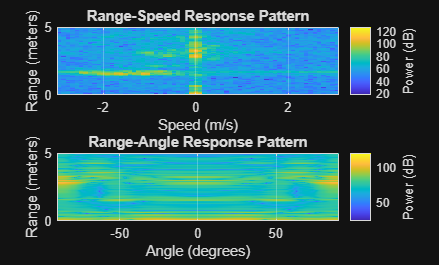


raResponse = phased.RangeAngleResponse(RangeMethod="FFT",...
    DechirpInput=false,SampleRate=fs,SweepSlope=sweepSlope,...
    SensorArray=vArray,OperatingFrequency=fc,ReferenceRangeCentered=false,);

adResponse = phased.AngleDopplerResponse(...
    'SensorArray',vArray,'OperatingFrequency',fc,...
    'PropagationSpeed',c,'PRF',prf);

figure;
yLimits=[0 5];
for i=1:dr.NumDataCubes
    cube = dr.read(1,i);
    cube = helperArrangeVirtualData(cube{1},radarConfiguration);
    subplot(2,1,1);
    plotResponse(rdResponse,squeeze(cube(:,1,:)));
    ylim(yLimits);
    % subplot(3,1,2);
    % [resp,ang_grid,dop_grid] = adResponse(cube(:,:,1)');
    % contour(ang_grid,dop_grid,abs(resp))
    % xlabel('Angle')
    % ylabel('Doppler')
    subplot(2,1,2);
    plotResponse(raResponse,cube(:,:,1));
    ylim(yLimits);
    drawnow limitrate;
end




function path = fileWithSuffix(folder,suffix)
    opts = dir(folder+"\*."+suffix);
    path = folder+"\"+opts(1).name;
end